# Розрахунково-Графічна робота

## студента: Красницького Микити.  Варіант - 6 

# Завдання 1

Розрахувати характеристики цифрового високочастотного фільтру з наступними параметрами: частотна межа смуги пропускання fp = 1.5*N + 1 кГц, частотна межа смуги затримання fs = 1.5*N кГц, нерівномірність АЧХ у межах смуги пропускання Rp = N/10 дБ, мінімально необхідне затухання у межах смуги затримання Rs = 40 + N дБ.

clear all
close all
N  = 6;             % Variant
fp = 1.5*N + 1;     % frequency bandwidth in kHz
fs = 1.5*N;         % the frequency limit of the detention band in kHz
e1 = N/10;          % unevenness in bandwidth area
e2 = 40 + N;        % min attenuation in the detention band

Використовуючи утиліту "Filter Design & Analysis" отримав коефіцієнти, що описують такий цифровий фільтр. Фільтр має 89 коефіцієнтів, що збережені у Num. Всі змінні збережені у файлі matlab.mat

order = 89;
Coef = [-0.00338624312359781 0.0110506986559087 ...
        -0.00461241706920057 -0.00418746089451992 0.000921008483443759 ...
        0.00408392003963552 0.00195384030569717 -0.00286955303792181 ...
        -0.00409535215830751 0.000386936994986559 0.00487815480100484 ...
        0.00284733873850759 -0.00365622914418071 -0.00567998230566269 ...
        0.0004008777006754 0.00674667767138341 0.00402658087342812 ...
        -0.00505344553836347 -0.00794321491001112 0.000505755355213545 ...
        0.00943395379239673 0.00568197501951673 -0.00704560390843225 ...
        -0.0112157128726449 0.000635904963238778 0.0133668224655996 ...
        0.00820564911821525 -0.0100248009271635 -0.0163104191017315 ...
        0.000753391480299663 0.0197502963689191 0.0125314396638012 ...
        -0.0151193693510508 -0.0255778593726268 0.00084729134761055 ...
        0.032513854464538 0.02191203985124 -0.0267746834342179 ...
        -0.0492423573237008 0.000907113481143685 0.0753397310639456 ...
        0.061330306922724 -0.0941034360515112 -0.302286887801558 ...
        0.600928629562226 -0.302286887801558 -0.0941034360515112 ...
        0.061330306922724 0.0753397310639456 0.000907113481143685 ...
        -0.0492423573237008 -0.0267746834342179 0.02191203985124 ...
        0.032513854464538 0.00084729134761055 -0.0255778593726268 ...
        -0.0151193693510508 0.0125314396638012 0.0197502963689191 ...
        0.000753391480299663 -0.0163104191017315 -0.0100248009271635 ...
        0.00820564911821525 0.0133668224655996 0.000635904963238778 ...
        -0.0112157128726449 -0.00704560390843225 0.00568197501951673 ...
        0.00943395379239673 0.000505755355213545 -0.00794321491001112 ...
        -0.00505344553836347 0.00402658087342812 0.00674667767138341 ...
        0.0004008777006754 -0.00567998230566269 -0.00365622914418071 ...
        0.00284733873850759 0.00487815480100484 0.000386936994986559 ...
        -0.00409535215830751 -0.00286955303792181 0.00195384030569717 ...
        0.00408392003963552 0.000921008483443759 -0.00418746089451992 ...
        -0.00461241706920057 0.0110506986559087 -0.00338624312359781];

Фільтр отримано. Генерую декілька вхідних сигналів щов впевнитися в правильності фільтра.

Заповнюю початок нулями.

Signal_in = 0;

for i = 1:order
    Signal_in(i) = 0;
end

Задаю сигнал на деякий час Т

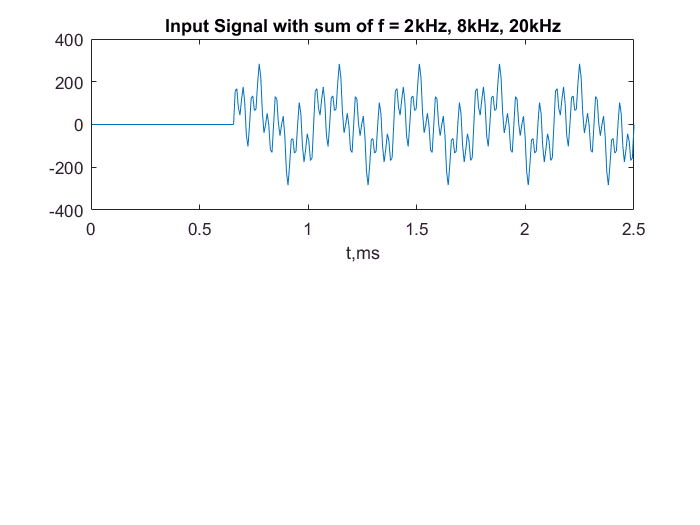

T   = 0.0025;        % 0.0005 sec
Sps = 100000;      % 10000k samples per second (for max freq in Signal_3 - 20kHz)
Nsamples = Sps * T;

t = ((1:(Nsamples+order)) / ((Nsamples+order)) ) * T * 1000;
w = 2*pi*[2 8 20] * 1000;

tt = (1:(Nsamples)) / Sps;

for i = 1:Nsamples
    Signal_in(i+order) = 100*( sin(w(1)*tt(i)) + sin(w(2)*tt(i)) + sin(w(3)*tt(i)) );
end

Реалізую проходження сигналу крізь фільтр. Через подвійний цикл реалізую різнецеве рівняння.

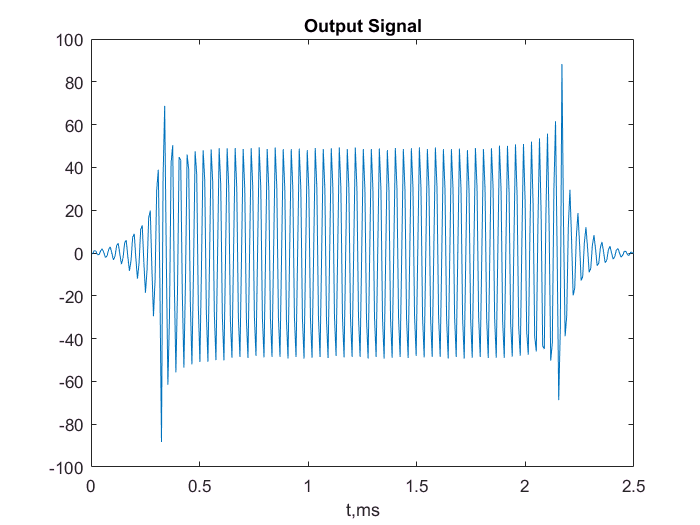

Signal_out = 0;

for i = 1:Nsamples+order
    Signal_out(i) = 0;
    
    for j = 1:order
        if(i+j < Nsamples+order)
            Signal_out(i) = Signal_out(i) + Coef(j)*Signal_in(i + j);
        end
    end
end

subplot(2,1,1);
plot(t,Signal_in);
title('Input Signal with sum of f = 2kHz, 8kHz, 20kHz');
xlabel('t,ms'); 

subplot(2,1, 2);
plot(t, Signal_out), title('Output Signal'), xlabel('t,ms'); 

Знайду спектри та побудую вхідні та вихідні спектри

L = Nsamples+order;

S1_t = abs([fft(Signal_in); fft(Signal_out)]) / L;

S1 = [S1_t(1, 1:L/2+1); S1_t(2, 1:L/2+1)];

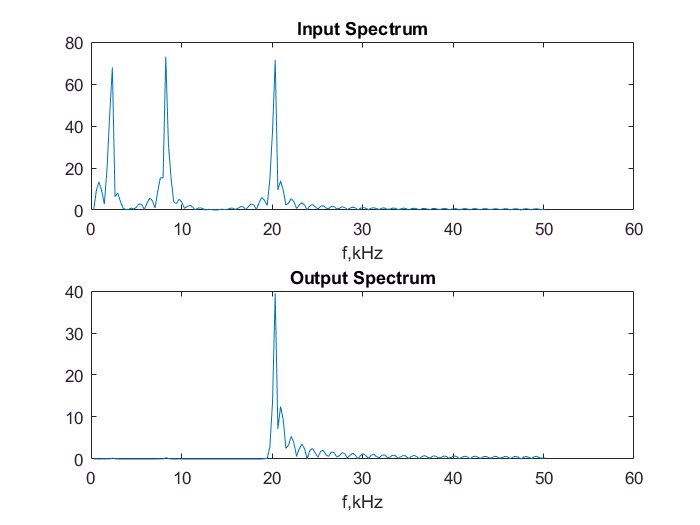


S1(1, 2:end-1) = 2*S1(1, 2:end-1);
S1(2, 2:end-1) = 2*S1(2, 2:end-1);

w = 100*(1 : (L/2 + 1)) / L ;

subplot(2, 1, 1), plot(w,S1(1,:)), title('Input Spectrum'),  xlabel('f,kHz');
subplot(2, 1, 2), plot(w,S1(2,:)), title('Output Spectrum'),  xlabel('f,kHz'); 